# Assignment 03 - A.A. 2023/24

close all
clear
clc

## 0) Data

Loading data and plotting time histories

% Loading data
load('Data')
t=Data(:,1);
F=Data(:,2);
x=Data(:,3:end);    % displacements in the 4 columns
np=size(x,1);        % number of samples
nj=size(x,2);        % number of displacements

dt=t(2)-t(1);        % acquisition period
fsamp=1/dt;            % sampling frequency
disp(' ')

disp(['Number of sensors: ' num2str(nj)])

Number of sensors: 4


disp(['dt [s]: ' num2str(dt)])

dt [s]: 0.001


disp(['np [-]: ' num2str(np)])

np [-]: 60001


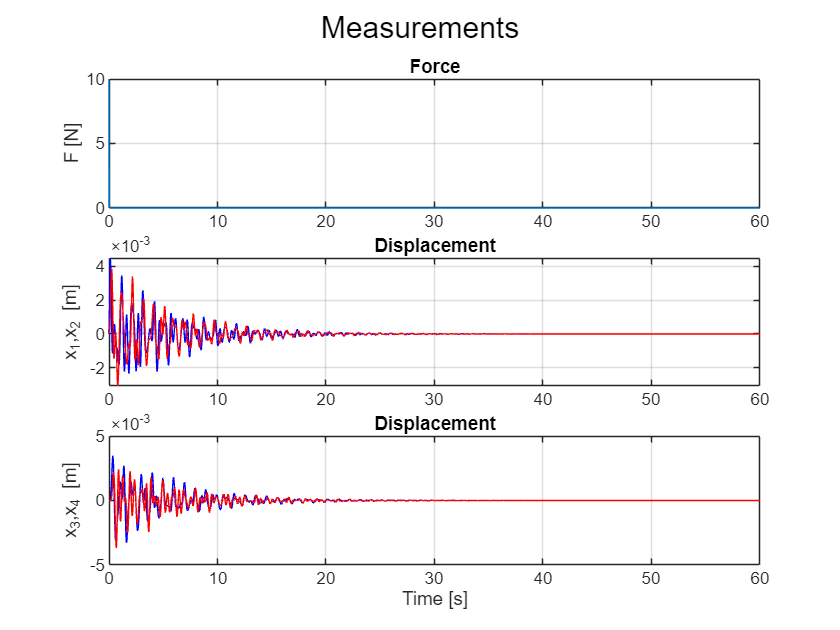


% Plotting all time histories
figure(1)
sf1(1)=subplot(3,1,1);
plot(t,F)
grid on
ylabel('F [N]')
title('Force')
sf1(2)=subplot(3,1,2);
plot(t,x(:,1),'b',t,x(:,2),'r')
grid on
ylabel('x_1,x_2 [m]')
title('Displacement')
sf1(3)=subplot(3,1,3);
plot(t,x(:,3),'b',t,x(:,4),'r')
grid on
xlabel('Time [s]')
ylabel('x_3,x_4 [m]')
title('Displacement')
linkaxes(sf1,'x')
sgtitle('Measurements')

## 1) Experimental FRF

Plot the "experimental" FRF diagrams.

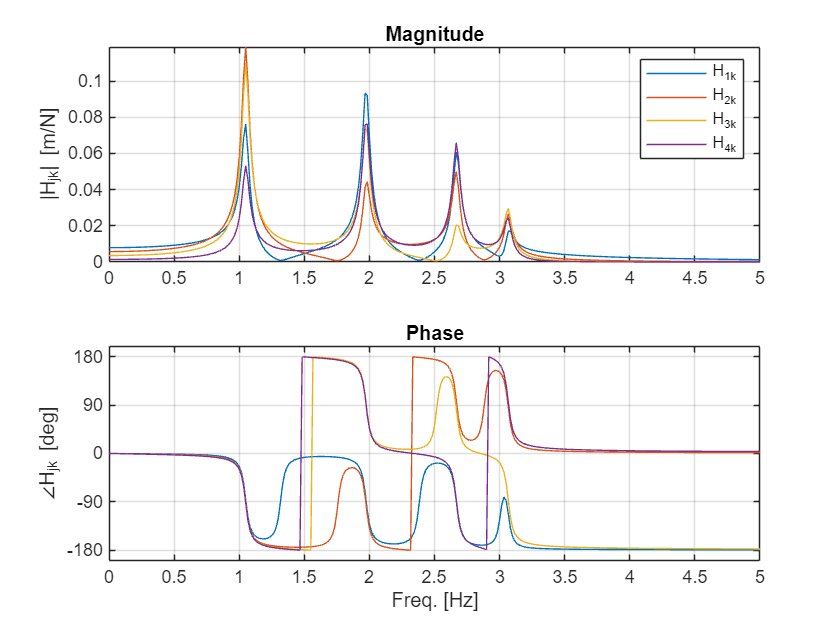

% Force and displacements spectra
[xfft,frq]=ffg(x,np,dt);
[Ffft,frq]=ffg(F,np,dt);

% Experimental FRFs = ratio output/input
Hjkexp = xfft./Ffft;

figure(2)
sf2(1)=subplot(2,1,1);

for jj=1:nj
    plot(frq,abs(Hjkexp(:,jj)))
    hold on
    legenda{jj}=['H_' num2str(jj) '_k'];
end

grid on
title('Magnitude')
%sgtitle('Experimental trasfer functions H_j_k')
ylabel(['|H_j_k| [m/N]'])
legend(legenda)

sf2(2)=subplot(2,1,2);

for jj=1:nj
    plot(frq,angle(Hjkexp(:,jj))*180/pi)
    hold on
end

grid on
ylabel('\angleH_j_k [deg]')
xlabel('Freq. [Hz]')
yticks([-180 -90 0 90 180])
title('Phase')
linkaxes(sf2,'x')
xlim([0 5])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parte da qui


## 2) Parameters estimation - simplified method

Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the range $0-5\;\textrm{Hz}$ employing simplified methods (e.g. half power point method). Comment the obtained results. 

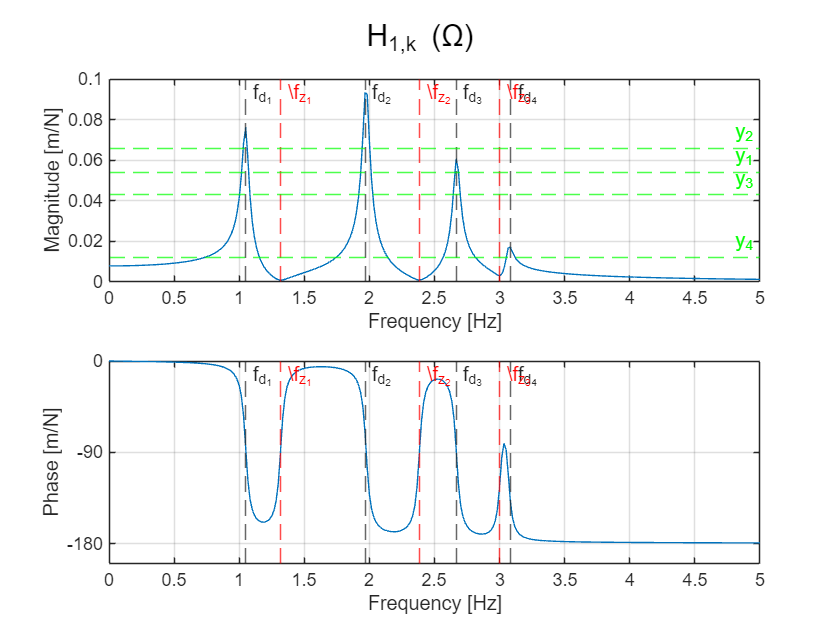

% FRF 1
f_damp1 = [1.0499, 1.9666, 2.6666, 3.0833];    % maxima
f_zero1 = [1.3166, 2.3833, 2.9999];            % minima
y_Q1 = [0.0762, 0.0933, 0.0607,  0.0170] ./ sqrt(2);
%df_1 = [0.0583, 0.0583];

figure()
sgtitle("H_{1,k} (\Omega)");

subplot(2, 1, 1);
plot(frq, abs(Hjkexp(:,1)))
grid on;
ylabel("Magnitude [m/N]");
xlabel("Frequency [Hz]");
xline(f_damp1(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp1(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp1(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp1(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero1(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
xline(f_zero1(2), LineStyle = "--", Color = "r", Label = "\f_{z_2}", LabelOrientation = "horizontal");
xline(f_zero1(3), LineStyle = "--", Color = "r", Label = "\f_{z_3}", LabelOrientation = "horizontal");
yline(y_Q1(1), LineStyle = "--", Color = "g", Label = "y_1");
yline(y_Q1(2), LineStyle = "--", Color = "g", Label = "y_2");
yline(y_Q1(3), LineStyle = "--", Color = "g", Label = "y_3");
yline(y_Q1(4), LineStyle = "--", Color = "g", Label = "y_4");
xlim([0, 5]);

subplot(2, 1, 2);
plot(frq, angle(Hjkexp(:,1))*180/pi)
grid on;
ylabel("Phase [m/N]");
xlabel("Frequency [Hz]");
yticks([-180 -90 0 90 180]);
xline(f_damp1(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp1(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp1(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp1(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero1(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
xline(f_zero1(2), LineStyle = "--", Color = "r", Label = "\f_{z_2}", LabelOrientation = "horizontal");
xline(f_zero1(3), LineStyle = "--", Color = "r", Label = "\f_{z_3}", LabelOrientation = "horizontal");
xlim([0, 5]);

### TO BE CHECKED

Computation of $h_i$:

$h_i =\frac{1}{\sqrt{1+{\left(2\pi \Delta \phi \right)}^2 }}$,    $\Delta \phi$ is phase slope

phase = angle(Hjkexp(:,1))*180/pi;
h_1 = [0, 0, 0, 0];

[~, idx] = min(abs(frq - f_damp1(1)));        % find the index of the frequency closest to f_n
phi_low = phase(idx - 1);                % phase at the lower frequency
phi_high = phase(idx + 1);                % phase at the higher frequency
delta_phi = phi_high - phi_low;            % change in phase
h_1(1) = 1 / sqrt(1 + (2*pi/delta_phi)^2);    % damping ratio

[~, idx] = min(abs(frq - f_damp1(2)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_1(2) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp1(3)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_1(3) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp1(4)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_1(4) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

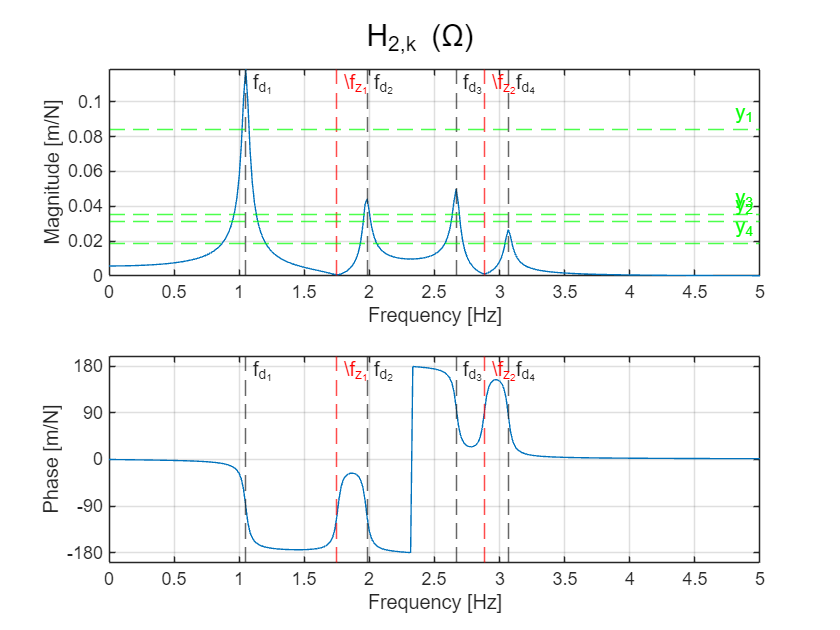

% FRF 2
f_damp2 = [1.0499, 1.9833, 2.6666, 3.0666];    % maxima
f_zero2 = [1.7499, 2.8833];                    % minima
y_Q2 = [0.1188, 0.0444, 0.0499,  0.0265] ./ sqrt(2);

figure()
sgtitle("H_{2,k} (\Omega)");

subplot(2, 1, 1);
plot(frq, abs(Hjkexp(:,2)))
grid on;
ylabel("Magnitude [m/N]");
xlabel("Frequency [Hz]");
xline(f_damp2(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp2(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp2(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp2(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero2(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
xline(f_zero2(2), LineStyle = "--", Color = "r", Label = "\f_{z_2}", LabelOrientation = "horizontal");
yline(y_Q2(1), LineStyle = "--", Color = "g", Label = "y_1");
yline(y_Q2(2), LineStyle = "--", Color = "g", Label = "y_2");
yline(y_Q2(3), LineStyle = "--", Color = "g", Label = "y_3");
yline(y_Q2(4), LineStyle = "--", Color = "g", Label = "y_4");
xlim([0, 5]);

subplot(2, 1, 2);
plot(frq, angle(Hjkexp(:,2))*180/pi)
grid on;
ylabel("Phase [m/N]");
xlabel("Frequency [Hz]");
yticks([-180 -90 0 90 180]);
xline(f_damp2(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp2(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp2(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp2(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero2(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
xline(f_zero2(2), LineStyle = "--", Color = "r", Label = "\f_{z_2}", LabelOrientation = "horizontal");
xlim([0, 5]);

### TO BE CHECKED

Computation of $h_i$:

$h_i =\frac{1}{\sqrt{1+{\left(2\pi \Delta \phi \right)}^2 }}$,    $\Delta \phi$ is phase slope

phase = angle(Hjkexp(:,2))*180/pi;
h_2 = [0, 0, 0, 0];

[~, idx] = min(abs(frq - f_damp2(1)));        % find the index of the frequency closest to f_n
phi_low = phase(idx - 1);                % phase at the lower frequency
phi_high = phase(idx + 1);                % phase at the higher frequency
delta_phi = phi_high - phi_low;            % change in phase
h_2(1) = 1 / sqrt(1 + (2*pi/delta_phi)^2);    % damping ratio

[~, idx] = min(abs(frq - f_damp2(2)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_2(2) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp2(3)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_2(3) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp2(4)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_2(4) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

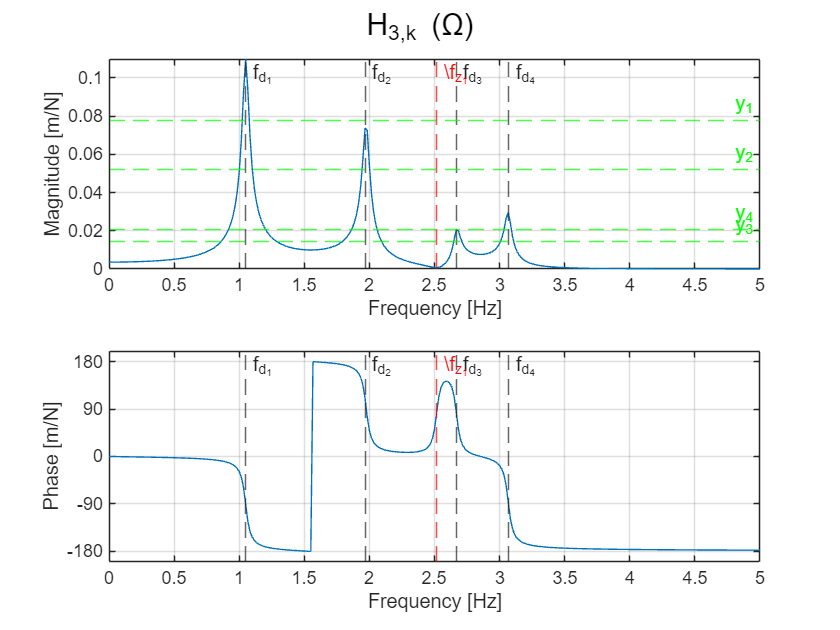

% FRF 3
f_damp3 = [1.0499, 1.9666, 2.6666, 3.0666];    % maxima
f_zero3 = [2.5166];                            % minima
y_Q3 = [0.1099, 0.0737, 0.0206,  0.0296] ./ sqrt(2);

figure()
sgtitle("H_{3,k} (\Omega)");

subplot(2, 1, 1);
plot(frq, abs(Hjkexp(:,3)))
grid on;
ylabel("Magnitude [m/N]");
xlabel("Frequency [Hz]");
xline(f_damp3(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp3(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp3(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp3(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero3(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
yline(y_Q3(1), LineStyle = "--", Color = "g", Label = "y_1");
yline(y_Q3(2), LineStyle = "--", Color = "g", Label = "y_2");
yline(y_Q3(3), LineStyle = "--", Color = "g", Label = "y_3");
yline(y_Q3(4), LineStyle = "--", Color = "g", Label = "y_4");
xlim([0, 5]);

subplot(2, 1, 2);
plot(frq, angle(Hjkexp(:,3))*180/pi)
grid on;
ylabel("Phase [m/N]");
xlabel("Frequency [Hz]");
yticks([-180 -90 0 90 180]);
xline(f_damp3(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp3(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp3(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp3(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xline(f_zero3(1), LineStyle = "--", Color = "r", Label = "\f_{z_1}", LabelOrientation = "horizontal");
xlim([0, 5]);

### TO BE CHECKED

Computation of $h_i$:

$h_i =\frac{1}{\sqrt{1+{\left(2\pi \Delta \phi \right)}^2 }}$,    $\Delta \phi$ is phase slope

phase = angle(Hjkexp(:,3))*180/pi;
h_3 = [0, 0, 0, 0];

[~, idx] = min(abs(frq - f_damp3(1)));        % find the index of the frequency closest to f_n
phi_low = phase(idx - 1);                % phase at the lower frequency
phi_high = phase(idx + 1);                % phase at the higher frequency
delta_phi = phi_high - phi_low;            % change in phase
h_3(1) = 1 / sqrt(1 + (2*pi/delta_phi)^2);    % damping ratio

[~, idx] = min(abs(frq - f_damp3(2)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_3(2) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp3(3)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_3(3) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp3(4)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_3(4) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

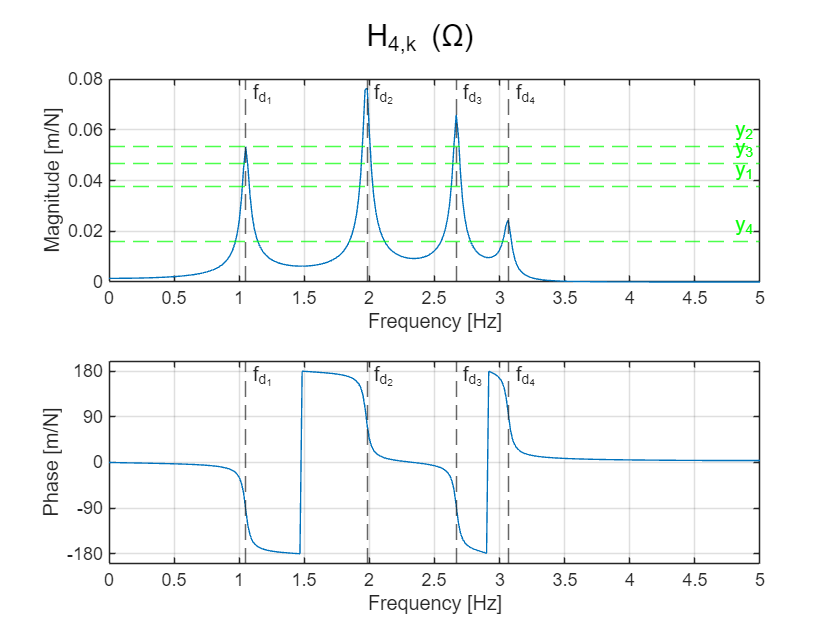

% FRF 4
f_damp4 = [1.0499, 1.9833, 2.6666, 3.0666];    % maxima
y_Q4 = [0.0532, 0.0757, 0.0659,  0.0225] ./ sqrt(2);

figure()
sgtitle("H_{4,k} (\Omega)");

subplot(2, 1, 1);
plot(frq, abs(Hjkexp(:,4)))
grid on;
ylabel("Magnitude [m/N]");
xlabel("Frequency [Hz]");
xline(f_damp4(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp4(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp4(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp4(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
yline(y_Q4(1), LineStyle = "--", Color = "g", Label = "y_1");
yline(y_Q4(2), LineStyle = "--", Color = "g", Label = "y_2");
yline(y_Q4(3), LineStyle = "--", Color = "g", Label = "y_3");
yline(y_Q4(4), LineStyle = "--", Color = "g", Label = "y_4");
xlim([0, 5]);

subplot(2, 1, 2);
plot(frq, angle(Hjkexp(:,4))*180/pi);
grid on;
ylabel("Phase [m/N]");
xlabel("Frequency [Hz]");
yticks([-180 -90 0 90 180]);
xline(f_damp4(1), LineStyle = "--", Label = "f_{d_1}", LabelOrientation = "horizontal");
xline(f_damp4(2), LineStyle = "--", Label = "f_{d_2}", LabelOrientation = "horizontal");
xline(f_damp4(3), LineStyle = "--", Label = "f_{d_3}", LabelOrientation = "horizontal");
xline(f_damp4(4), LineStyle = "--", Label = "f_{d_4}", LabelOrientation = "horizontal");
xlim([0, 5]);

### TO BE CHECKED

Computation of $h_i$:

$h_i =\frac{1}{\sqrt{1+{\left(2\pi \Delta \phi \right)}^2 }}$,    $\Delta \phi$ is phase slope

phase = angle(Hjkexp(:,4))*180/pi;
h_4 = [0, 0, 0, 0];

[~, idx] = min(abs(frq - f_damp4(1)));        % find the index of the frequency closest to f_n
phi_low = phase(idx - 1);                % phase at the lower frequency
phi_high = phase(idx + 1);                % phase at the higher frequency
delta_phi = phi_high - phi_low;            % change in phase
h_4(1) = 1 / sqrt(1 + (2*pi/delta_phi)^2);    % damping ratio

[~, idx] = min(abs(frq - f_damp4(2)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_4(2) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp4(3)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_4(3) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

[~, idx] = min(abs(frq - f_damp4(4)));
phi_low = phase(idx - 1);
phi_high = phase(idx + 1);
delta_phi = phi_high - phi_low;
h_4(4) = 1 / sqrt(1 + (2*pi/delta_phi)^2);

## 3) Residual minimization

Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.

## 4) Comparisons

Compare and comment the identified modal parameters with ones obtained with the above-mentioned methods.

## 5) Modal approach - FRF reconstruction

Employing a modal approach, reconstruct the FRFs and compare with the “experimental” original ones.